# Exam admission assignment - Navigation

This assignment is mandatory for all students of mobile robots to get the admission to participate in the exam.

The assignment will treat a navigation task, combining already familiar local and global planner.

On the presentation date you have to present the 

clear all;
close all;

1) Initiate Matlab node

matlab_node = ros2node('matlab_node');

2) Initiate a velocity publisher and a subscriber for the current pose ("/odom") 

velPub = ros2publisher(matlab_node, "/cmd_vel");
odomSub = ros2subscriber(matlab_node,"/odom");

3) Initiate a goal subscriber to the "/goal_pose" topic from RVIZ with a subscriber callback that fills the values of the goal handle. 

goalHandle = PoseHandle();
goalSub = ros2subscriber(matlab_node, "/goal_pose", "geometry_msgs/PoseStamped", {@goalCallback, goalHandle});

4) Load the map and display it. Also add the goal pose.

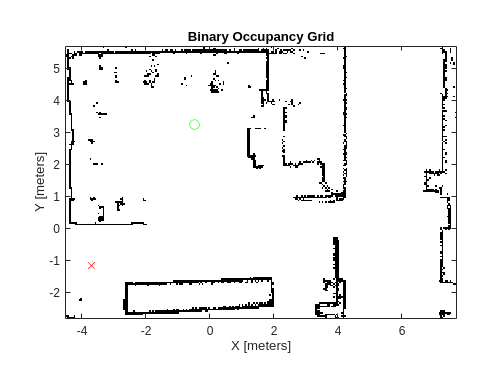

% Load image
map_img =imread("rst_lab_cropped.pgm");

% Required steps to align the map correctly (do not change!)
bwimage = map_img < 100;
bwimage = imrotate(bwimage, 90);
map = binaryOccupancyMap(bwimage, 1/0.05);
map.GridLocationInWorld = [-4.5, -2.8];


figure("Name", "Map");
map.show;
hold on;

opose = odomSub.LatestMessage;
[robot_x, robot_y, robot_theta] = OdometryMsg2Pose(opose);

% Plot the robot pose
plot(robot_x,robot_y,'go', 'MarkerSize', 8);

% Get transformation tree for goal pose
tfTree=ros2tf(matlab_node);
pause(1)

% Transform goalHandle
goalPose = goalHandle2goalPose(goalHandle,tfTree);

% Plot goal
goal_x = goalPose.pose.position.x;
goal_y = goalPose.pose.position.y;
goal_theta = quat2eul([goalPose.pose.orientation.w goalPose.pose.orientation.x goalPose.pose.orientation.y goalPose.pose.orientation.z]);
goal_theta = goal_theta(1);
plot(goal_x,goal_y, 'rx', 'MarkerSize', 8);

5) Implement PRM and RRT as global path planners for the lab environment regarding the current robot pose.

% generate global plan
global_planner = "PRM";

start_pose =[robot_x,robot_y,robot_theta];
goal_pose = [goal_x,goal_y,goal_theta];
stateSpace = stateSpaceSE2;
stateValidator = validatorOccupancyMap(stateSpace);
stateValidator.Map = map;
stateSpace.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];
stateValidator.ValidationDistance = 0.01;

switch global_planner
    case "PRM"
        disp("Executing PRM...");
        maxNumNodes = 300;
        planner = plannerPRM(stateSpace,stateValidator,"MaxNumNodes",maxNumNodes,"MaxConnectionDistance",1.5);

        % Visualize roadmap
        show(stateValidator.Map); hold on;
        
        graph = graphData(planner);
        nodes = table2array(graph.Nodes);
        edges = table2array(graph.Edges);

        % draw nodes
        plot(nodes(:,1), nodes(:,2), '*b', 'LineWidth', 2);

        % draw edges
        for i = 1:size(edges,1)
            seg = interpolate(stateSpace, nodes(edges(i,1),:),nodes(edges(i,2),:), 0:0.05:1);
            plot(seg(:,1), seg(:,2), 'b');
        end

        % plot start and goal
        plot(start_pose(1),start_pose(2), '*g', 'LineWidth', 3);
        plot(goal_pose(1),goal_pose(2), '*r', 'LineWidth', 3);

        % plan path
        [path, solnInfo] = plan(planner, start_pose, goal_pose);

        % visualize path
        if solnInfo.IsPathFound
            plot(path.States(:,1),path.States(:,2), 'Color', [0.85 0.325 0.098], 'LineWidth', 2);
        else
            warning('PRM: Path not found');
        end
        hold off;
        plannedPath = path.States;

    case "RRT"
        disp("Executing RRT...");
        planner = plannerRRT(stateSpace,stateValidator);
        planner.MaxIterations = 20000;
        planner.MaxConnectionDistance = 0.8;

        % plan
        [path, solnInfo] = plan(planner,start_pose,goal_pose);

        % Visualize
        show(stateValidator.Map); hold on;
        plot(start_pose(1),start_pose(2), '*g', 'LineWidth', 3);
        plot(goal_pose(1),goal_pose(2), '*r', 'LineWidth', 3);

        % PLot Tree
        plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-');
        % Plot Path
        plot(path.States(:,1),path.States(:,2), 'r-', 'LineWidth', 2);

        plannedPath = path.States;

    otherwise
        error('Unknown global planner: %s', global_planner);
end

Executing PRM...


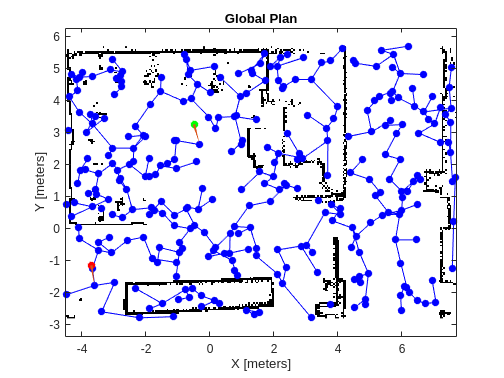

title('Global Plan');
axis equal;

6) Optimize the path

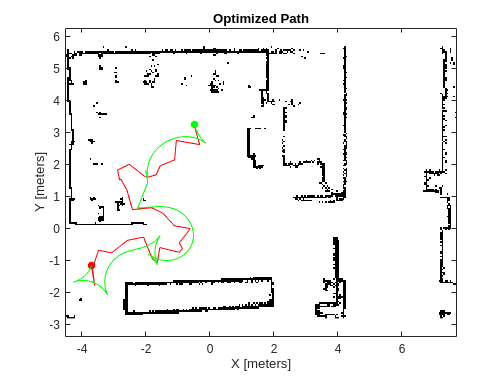

options = optimizePathOptions;

% Optimize the path generated by the planner.
[optimizedPath, kineticInfo, solutionInfo] = optimizePath(plannedPath,map,options);
figure;


show(stateValidator.Map); hold on;

% Plot start, end, planned and optimized path
plot(start_pose(1),start_pose(2) , '*g', 'LineWidth', 3);
plot(goal_pose(1),goal_pose(2) , '*r', 'LineWidth', 3);
plot(plannedPath(:,1),plannedPath(:,2), 'r-', 'LineWidth', 1);
plot(optimizedPath(:,1),optimizedPath(:,2) , 'g-', 'LineWidth', 2);
title('Optimized Path');
axis equal;

drawnow;

7) Implement the teb planner for path following and obstacle avoidance

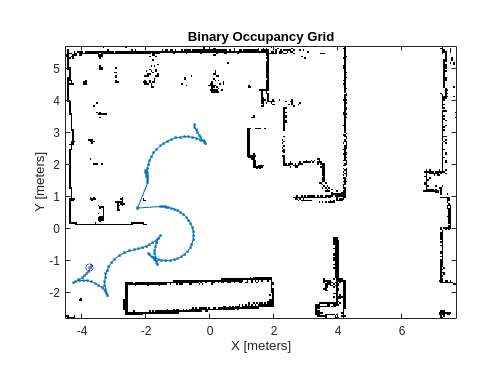

TEB=true;

refpath = optimizedPath;
teb = controllerTEB(refpath, map);
teb.RobotInformation.Shape = "Rectangle";
teb.RobotInformation.Dimension = [0.2 0.2];
teb.LookAheadTime = 5.0;
teb.MaxVelocity = [0.5 1.5];
teb.MaxAcceleration = [0.5 0.5];
teb.ReferenceDeltaTime = 0.3;
teb.ObstacleSafetyMargin = 0.1;

rate = robotics.Rate(5);
goalReached = false;

% Current velocity and pose
curvel = [0 0];
curpose = [0 0 0];   

while ~goalReached
    % Update current pose
    opose = receive(odomSub,2);
    [cur_x, cur_y, cur_theta] = OdometryMsg2Pose(opose);

    % Take last velocity
    curpose = [cur_x, cur_y, cur_theta];
    curvel = [opose.twist.twist.linear.x, opose.twist.twist.angular.z];

    % Get next steps from TEB
    [velcmds, tstamps, curpath, info] = step(teb,curpose,curvel);
    goalReached = info.HasReachedGoal;

    % Visualization (simple)
    clf;
    show(map); hold on;
    plot(refpath(:,1), refpath(:,2), '.-');
    plot(curpath(:,1), curpath(:,2), '.-');
    plot(cur_x, cur_y, 'bo');
    drawnow;

    % Publish cmd_vel
    msg = ros2message(velPub);
    msg.linear.x = velcmds(1,1);  
    msg.angular.z = velcmds(1,2);
    send(velPub, msg);

    
    waitfor(rate);
end


disp('Goal reached.');

Goal reached.


for i = 1:3    
    msg.linear.x=0;
    msg.angular.z=0;
    send(velPub,msg);
    pause(0.1);
end

### Helper functions you have to implement

function [] = goalCallback(msg,goalHandle)

goalHandle.x = msg.pose.position.x;
goalHandle.y = msg.pose.position.y;
q = [msg.pose.orientation.w,msg.pose.orientation.x,msg.pose.orientation.y,msg.pose.orientation.z];
eul = quat2eul(q);
goalHandle.theta = eul(1);

disp("Received goal");
disp([goalHandle.x, goalHandle.y, goalHandle.theta]);

end

### Helper functions that are given

function [ x, y, theta ] = OdometryMsg2Pose(poseMsg)
% convert odometry message to vector
% 2007 - Frank Hoffmann
x=poseMsg.pose.pose.position.x;
y=poseMsg.pose.pose.position.y;
eul=quat2eul([poseMsg.pose.pose.orientation.w poseMsg.pose.pose.orientation.x  poseMsg.pose.pose.orientation.y poseMsg.pose.pose.orientation.z]);
theta=eul(1);
end

function goalPose = goalHandle2goalPose(goalHandle,tfTree)
pt = ros2message('geometry_msgs/PoseStamped');
pt.header.frame_id = 'map';
pt.pose.position.x = goalHandle.x;
pt.pose.position.y = goalHandle.y;
pt.pose.position.z = 0;
quat = axang2quat([0 0 1 goalHandle.theta]);
pt.pose.orientation.w = quat(1);
pt.pose.orientation.x = quat(2);
pt.pose.orientation.y = quat(3);
pt.pose.orientation.z = quat(4);
goalPose = transform(tfTree,'odom',pt);

% goalPose = [goalHandle.x,goalHandle.y,goalHandle.theta];
end


